# Allocating Resources After a Major Weather Event

## Background and Scope

### Import the Data

You may use an import function. If not using an import function, include the code used to import the data (it may be generated from the Import Tool)

StormEvents2017 = readtable("StormEvents_2017_finalProject.csv");

### Two States Most Impacted by Harvey

Clearly state the two states in order 

% select specific focus states - Arkansas, Kentucky, Louisiana, Mississippi, North Carolina, Tennessee, and Texas.
StormEvents2017 = StormEvents2017(ismember(StormEvents2017.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);

% We may assume Harvey events occurred only from the 17 August to 3 September 
% therefore, limit data to August and September month
StormEvents2017 = StormEvents2017(ismember(StormEvents2017.Month,{'August','September'}),:);

% find the two most impacted states in terms of property cost
summary = groupsummary(StormEvents2017, "State", "sum", "Property_Cost");
sortrows(summary,'sum_Property_Cost','descend'); 

The two most important states are: **Texas** and **Louisiana**

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

% Limit table to Texas and Louisiana
StormEvents2017 = StormEvents2017(StormEvents2017.State == "LOUISIANA"|StormEvents2017.State == "TEXAS", :);
head(StormEvents2017)

ans = 8×24 table
    EpisodeID      Event_ID       State      Year        Month             Event_Type             CZ_Name          Begin_Date_Time      Timezone        End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                            

## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

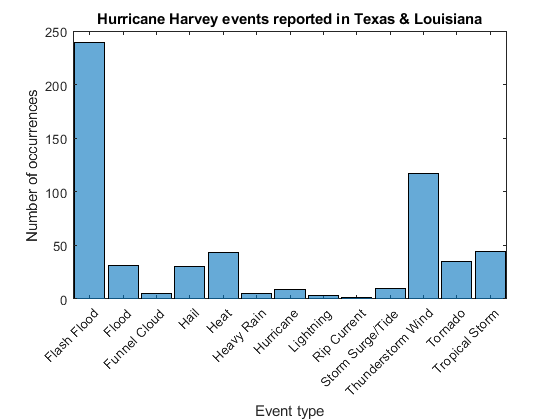

% Histogram plot of event types and # of occurrences
StormEvents2017.Event_Type = categorical(StormEvents2017.Event_Type);
histogram(StormEvents2017.Event_Type)

xlim({'Flash Flood','Tropical Storm'})
ylim([0 250])
title('Hurricane Harvey events reported in Texas & Louisiana')
xlabel('Event type')
ylabel('Number of occurrences')

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

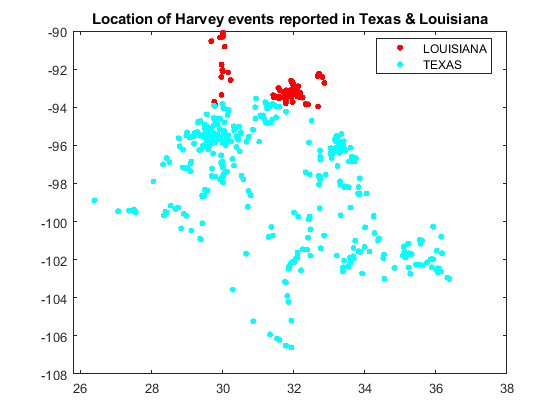

% gscatter plot of event location in two states
StormEvents2017.State = categorical(StormEvents2017.State);
gscatter(StormEvents2017.Begin_Lat,StormEvents2017.Begin_Lon,StormEvents2017.State)

title('Location of Harvey events reported in Texas & Louisiana')

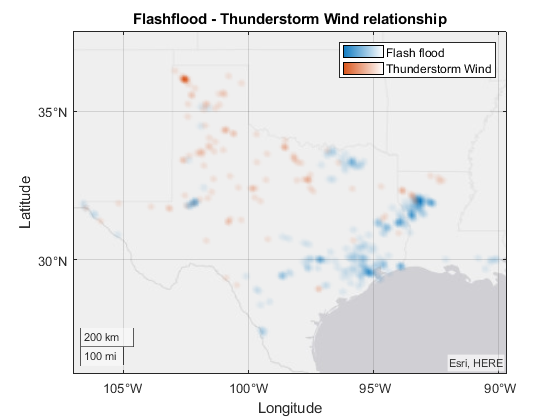


% Add-on: relationship btw two most important events - Flashflood and
% Thunderstorm Wind 

FF = StormEvents2017.Event_Type=="Flash Flood";
geodensityplot(StormEvents2017.Begin_Lat(FF),StormEvents2017.Begin_Lon(FF))

% Add Thunderstorm Wind to see if they are related.
hold on
TWind = StormEvents2017.Event_Type=="Thunderstorm Wind";
geodensityplot(StormEvents2017.Begin_Lat(TWind),StormEvents2017.Begin_Lon(TWind))
hold off

title('Flashflood - Thunderstorm Wind relationship')
legend({'Flash flood','Thunderstorm Wind'})

## Analysis

### Three Counties with Most Events in State 1

% limit data to select state1(Texas) data
StormEvents2017_1 = StormEvents2017(StormEvents2017.State == "TEXAS",:);

% three counties with the most events in state 1
groupsummary(StormEvents2017_1, 'CZ_Name');

Counties with the most events in Texas are **Harris**, **Galveston** and **Brazoria**

### Three Counties with Most Events in State 2

% limit data to select state2(Louisiana) data
StormEvents2017_2 = StormEvents2017(StormEvents2017.State == "LOUISIANA",:);

% three counties with the most events in state 2
groupsummary(StormEvents2017_2, 'CZ_Name');

Counties with the most events in Louisiana are **Natchitoches**, **Sabine** and **Red river. **

### Three Counties with Highest Property Cost in State 1

groupsummary(StormEvents2017_1, 'CZ_Name', 'sum', 'Property_Cost');

Counties with the highest property cost in Texas include **Galveston**, **Fort Bend**, and **Montgomery **with costs amounting to about $20 billion, $16 billion and $14 billion respectively.  

### Three Counties with Highest Property Cost in State 2

groupsummary(StormEvents2017_2, 'CZ_Name', 'sum', 'Property_Cost');

Counties with the highest property cost in Louisiana include **Calcasieu**, **Beauregard**, and **Orleans **with costs amounting to $60million, $15million and $6million respectively. 

## Conclusions and Recommendations

The results of the data analysis shows that the counties with the most harvey events (in both Texas and Louisiana) have not incurred the highest cost in property damage. However, there is only one exception to this statement, in the case of the Galveston county in Texas which has the second highest number of events as well as the highest reported property cost.  

The results of the data analysis also showed that harvey events has led to higher cost of property damage in Texas (billions of dollars) than in Louisiana (millions of dollars). Therefore, we recommend that more people should be sent to counties in Texas than Louisiana, especially to the top 3 counties having the highest property costs. The Galveston county in Texas should have the highest priority among the Texas counties. While the Calcasieu county should have the highest priority among the Louisiana counties. 